# Plots

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Qband spectrum with lines at g = 2.003 and g = 2.0065

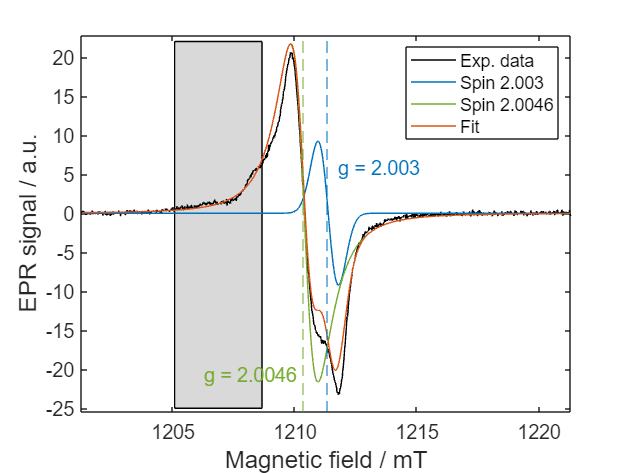

load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
load('data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat');
load("ColorsPlot.mat");
ICW = 5;

Sys0.g = Fit.pfit(1);
Sys0.lwpp(2) = Fit.pfit(2);
Sys1.g = Fit.pfit(3);
Sys1.lwpp(1) = Fit.pfit(4);
Sys1.weight = Fit.pfit(5);

Exp = Fit.argsfit{1, 2};
Opt.Output = 'separate';

yFit = Fit.scale*pepper({Sys0, Sys1}, Exp, Opt);

figure()
plot(cw(ICW).x, -real(cw(ICW).y2), 'Color', PlotColors(1), 'DisplayName', 'Exp. data')
hold on
plot(cw(ICW).x, Fit.fit, 'Color', PlotColors(2), 'DisplayName', 'Fit')
plot(cw(ICW).x, yFit(1, :), 'Color',  PlotColors(3),  'DisplayName', 'Spin 2.0046')
plot(cw(ICW).x, yFit(2, :), 'Color',  PlotColors(4), 'DisplayName', 'Spin 2.003')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.0046), '--', 'Color', PlotColors(3), 'HandleVisibility', 'off')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.003), '--', 'Color', PlotColors(4), 'HandleVisibility', 'off')
rectangle('position', [cw(ICW).x(195) -25 (cw(ICW).x(378) - cw(ICW).x(195)) 47], 'FaceColor', [.85 .85 .85])

    Label3 = "g = 2.003";
text(0.525, 0.65, Label3, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', PlotColors(4));
Label4 = "g = 2.0046";
text(0.25, 0.1, Label4, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', PlotColors(3));

chH = get(gca, "Children");
set(gca,'Children',[chH(6);chH(5);chH(4);chH(7);chH(3);chH(2);chH(1)])

ylim(setAxLim(real(-cw(ICW).y2), 0.05))
xlim(setAxLim(cw(ICW).x, 0))
legend()
labelAxesFig(gca, "Magnetic field / mT", "EPR signal / a.u.")
exportFig(gcf, 'images', 'sijia-fig-00001', '.svg')